gurobi_setup;


The MATLAB interface for Gurobi 10.0.1 has been installed.

The directory
    C:\gurobi1001\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2023
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.37.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle 

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

% setenv('GUROBI_PATH', 'C:\gurobi1001\win64\matlab')
% changeCobraSolver('gurobi', 'all')

## Load the data

Load the transcriptomics data, the housekeeping genes obtained in the previous script, and the metabolic model (Human1 version).

% Transcriptomics data
data = readtable('Mod_data.xlsx');
% Housekeeping genes with the ensembl ids
h_k_g = readtable('housekeeping_ens.csv');
% Human1 metabolic model.
model = readCbModel('Human-GEM_Cobra_v1.01.mat');

Each model.subSystems{x} is a cell array, allowing more than one subSystem per reaction.


## Metabolic genes

### Pick the genes related to metabolism

In the transcriptomics dataset there are a lot of genes, but we are interested just in those ones that take part in the metabolism, so, we are going to compare the ensembl id of both, the transcriptomics dataset and the Human1 metabolic model, and pick those ones that are present.

% Create a vector just with the ensembl ids of the genes from the model
model_genes = model.genes

model_genes = 3068×1 cell array
    {'ENSG00000000419'}
    {'ENSG00000001036'}
    {'ENSG00000001084'}
    {'ENSG00000001630'}
    {'ENSG00000002549'}
    {'ENSG00000002587'}
    {'ENSG00000002726'}
    {'ENSG00000002746'}
    {'ENSG00000003137'}
    {'ENSG00000003987'}
    {'ENSG00000003989'}
    {'ENSG00000004455'}
    {'ENSG00000004468'}
    {'ENSG00000004478'}
    {'ENSG00000004779'}
    {'ENSG00000004799'}
    {'ENSG00000004809'}
    {'ENSG00000004864'}
    {'ENSG00000004939'}
    {'ENSG00000004961'}
    {'ENSG00000005022'}
    {'ENSG00000005075'}
    {'ENSG00000005187'}
    {'ENSG00000005339'}
    {'ENSG00000005381'}
    {'ENSG00000005421'}
    {'ENSG00000005469'}
    {'ENSG00000005471'}
    {'ENSG00000005483'}
    {'ENSG00000005810'}


% Find indexes of the genes that are present in the metabolic model. 
index_names = ismember(data.Ensembl_GeneID, model_genes);
% take the rows of the dataset that match the indexes obtained before, with all the data 
data_met = data(index_names, :)

data_met = 3033×49 table
      Ensembl_GeneID         BJ_Y1        BJ_Y2        BJ_Y3      BJ_OLD_1     BJ_OLD_2     BJ_OLD_3    IMR90_Y1     IMR90_Y2    IMR90_Y3    IMR90_O1    IMR90_O2    IMR90_O3     WI_38_Y1     WI_38_Y2     WI_38_Y3     WI_38_O1     WI_38_O2    WI_38_O3    HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    MRC_5_PD72_1    MRC_5_PD72_2    MRC_5_PD72_3    HFF_PD

## StanDep

The first step is to check the if the model contain blocked reactions that can affect the interpretation. 

%First, in all model extraction it is good to pre_process the model to
%ensure it does not contain blocked reactions

[fluxConsistentMetBool, fluxConsistentRxnBool, fluxInConsistentMetBool, fluxInConsistentRxnBool, ~, fluxConsistModel] = findFluxConsistentSubset(model);
model = fluxConsistModel

model = struct with fields:
                          S: [7114×11831 double]
                       mets: {7114×1 cell}
                          b: [7114×1 double]
                     csense: [7114×1 char]
                       rxns: {11831×1 cell}
                         lb: [11831×1 double]
                         ub: [11831×1 double]
                          c: [11831×1 double]
                  osenseStr: 'max'
                      genes: {2495×1 cell}
                      rules: {11831×1 cell}
                  compNames: {9×1 cell}
                      comps: {9×1 cell}
                 metCharges: [7114×1 int64]
                metFormulas: {7114×1 cell}
                   metNames: {7114×1 cell}
             metInChIString: {7114×1 cell}
                    grRules: {11831×1 cell}
                 rxnGeneMat: [11831×2495 double]
        rxnConfidenceScores: [11831×1 double]
                   rxnNames: {11831×1 cell}
                   rxnNotes: {11831×1 cell}
        

model

model = struct with fields:
                          S: [7114×11831 double]
                       mets: {7114×1 cell}
                          b: [7114×1 double]
                     csense: [7114×1 char]
                       rxns: {11831×1 cell}
                         lb: [11831×1 double]
                         ub: [11831×1 double]
                          c: [11831×1 double]
                  osenseStr: 'max'
                      genes: {2495×1 cell}
                      rules: {11831×1 cell}
                  compNames: {9×1 cell}
                      comps: {9×1 cell}
                 metCharges: [7114×1 int64]
                metFormulas: {7114×1 cell}
                   metNames: {7114×1 cell}
             metInChIString: {7114×1 cell}
                    grRules: {11831×1 cell}
                 rxnGeneMat: [11831×2495 double]
        rxnConfidenceScores: [11831×1 double]
                   rxnNames: {11831×1 cell}
                   rxnNotes: {11831×1 cell}
        

Change the name of the column that contains the Ensembl_ID to gene, and normalize the data, 

%Ensuring that the first colum is names 'gene' 
data_met.Properties.VariableNames{1} = 'gene';
%Although this is not documented clearly, standep will perform a log10 on
%the expression data. To ensure that this does not introduce negative
%numbers we add 1 everywhere.
datalog10 = data_met

datalog10 = 3033×49 table
           gene              BJ_Y1        BJ_Y2        BJ_Y3      BJ_OLD_1     BJ_OLD_2     BJ_OLD_3    IMR90_Y1     IMR90_Y2    IMR90_Y3    IMR90_O1    IMR90_O2    IMR90_O3     WI_38_Y1     WI_38_Y2     WI_38_Y3     WI_38_O1     WI_38_O2    WI_38_O3    HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    MRC_5_PD72_1    MRC_5_PD72_2    MRC_5_PD72_3    HFF_P

datalog10{:,2:end} = log10(datalog10{:,2:end}+1)

datalog10 = 3033×49 table
           gene              BJ_Y1        BJ_Y2        BJ_Y3      BJ_OLD_1     BJ_OLD_2     BJ_OLD_3     IMR90_Y1     IMR90_Y2    IMR90_Y3    IMR90_O1     IMR90_O2    IMR90_O3     WI_38_Y1     WI_38_Y2     WI_38_Y3     WI_38_O1     WI_38_O2    WI_38_O3    HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    MRC_5_PD72_1    MRC_5_PD72_2    MRC_5_PD72_3    HFF

Define the limits of the bins:

%Standep requires us to define the bin boundaries. IMPORTANTLY these
%boundaries have to be in a log scale...
maxlog10 = max(max(table2array(datalog10(:,2:end))));
edgeX = linspace(0,maxlog10,11); %If we want 10 bins we need 11 
edgeX = round(edgeX,1); %These are our bin bounds!

Pre-processing of the data for Standep

%Standep requires a very specific pre-processing for the inputs!
%1st, the RNA data structure
rnaData = struct();
rnaData.gene = data_met.gene;
rnaData.value = table2array(data_met(:,2:end));
rnaData.valuebyTissue = table2array(data_met(:,2:end));
rnaData.Tissue = data.Properties.VariableNames(2:end)';

Pre-processing of the metabolic model

%2nd the model data structure
modelData = getModelData(rnaData,model);

Pre-processing of the enzyme data 

%3rd the enzyme data structure
spec = getSpecialistEnzymes(model);  
prom = getPromEnzymes(model);
enzymeData = comparePromiscuousSpecific(spec,prom,modelData);

Set the parameters for the clustering analysis

% We then set our parameters...
distMethod = 'euclidean'; % distance method  maybe think one more robust than euclidean.
linkageMethod = 'complete'; % linkage metric for hierarchical clustering
k = 10;

Clustering analysis

Cophenetic correlation coeffcient using complete linkage and euclidean distance = 0.8784


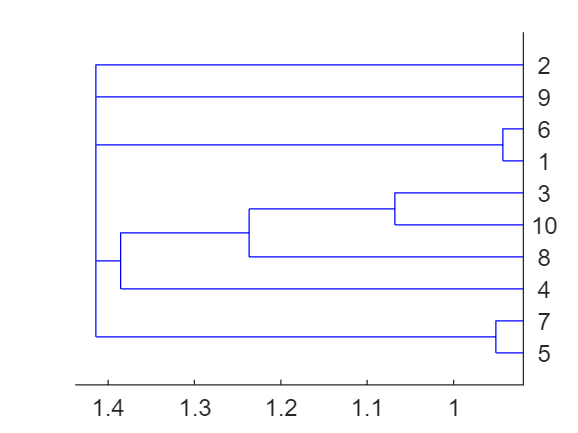

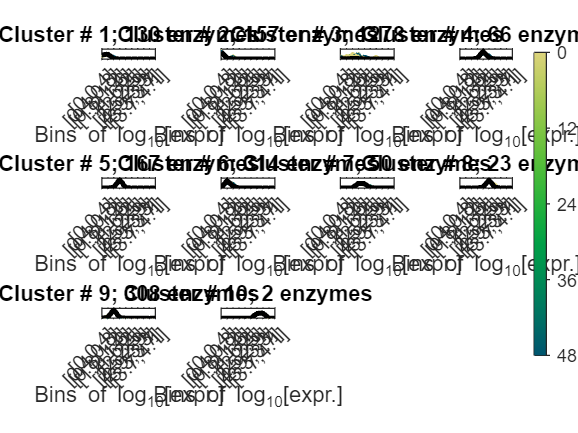

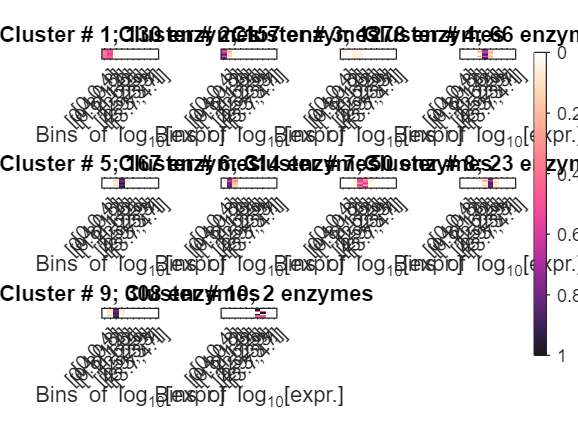

close all %This is important to ensure that all standep plots have the right number to be saved if we wish
clustObj = geneExprDist_hierarchy(enzymeData,[],edgeX,k,distMethod,linkageMethod);

Identify core reactions and calculate ubiquity score?

[coreRxnMat,enzTis,cutOff,thr] = models4mClusters1(clustObj,enzymeData.Tissue,model,edgeX,[],[],false,0,[1 1]); %CoreRxnMat defines the core set of reactions in a general sense

Top 25th percentile for the data = 1.0211
Mean of Data = 0.1716
Std. Dev. of Data = 0.2575
fraction selected = 0.0002
fraction selected = 0.0001
fraction selected = 0.0000
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000
fraction selected = 1.0000


[ubiScore,uScore] = getUbiquityScore_2022(clustObj,edgeX,model); %ubiScore is the ubiquity score per rxns to use in mCadre!

Top 25th percentile for the data = 1.0211
Mean of Data = 0.1716
Std. Dev. of Data = 0.2575


coreRxnTable = 11831×48 table
                coreRxnMat1    coreRxnMat2    coreRxnMat3    coreRxnMat4    coreRxnMat5    coreRxnMat6    coreRxnMat7    coreRxnMat8    coreRxnMat9    coreRxnMat10    coreRxnMat11    coreRxnMat12    coreRxnMat13    coreRxnMat14    coreRxnMat15    coreRxnMat16    coreRxnMat17    coreRxnMat18    coreRxnMat19    coreRxnMat20    coreRxnMat21    coreRxnMat22    coreRxnMat23    coreRxnMat24    coreRxnMat25    coreRxnMat26    coreRxnMat27    coreRxnMat28    coreRxnMat29    

hkg_met_ens = 1158×1 table
           gene        
    ___________________

    {'ENSG00000000419'}
    {'ENSG00000001084'}
    {'ENSG00000001630'}
    {'ENSG00000002549'}
    {'ENSG00000004455'}
    {'ENSG00000004478'}
    {'ENSG00000004779'}
    {'ENSG00000004961'}
    {'ENSG00000005022'}
    {'ENSG00000005075'}
    {'ENSG00000005339'}
    {'ENSG00000005810'}
    {'ENSG00000005882'}
    {'ENSG00000006007'}
    {'ENSG00000006530'}
    {'ENSG00000006625'}


Thanks to StanDep, a matrix has been generated with the reactions that are considered core (1) and non-core (0), however, no solution has been found to obtain from the list of housekeeping genes, the list of reactions that they encode, since as we know, many genes come into play, and some could be considered as non housekeeping. At the same time, an attempt was also made to convert reactions into genes, in order to be able to analyse them, but genes that were not known to exist were found. Therefore, no progress was made in this field, but it is hoped that a solution will be found in the future.